# Offline RL for GBWM — Week 7: Continuous Action Space via DDPG

First fundamental algorithm change of the project. All prior versions (Plan C / 6.0 / 6.0b / 6.1 / 7.0 / 7.0b) used DQN with 15 discrete actions corresponding to fixed efficient-frontier portfolios. This file replaces DQN with DDPG (Deep Deterministic Policy Gradient) and treats the action as a single continuous risk-position scalar α ∈ [0, 1] that smoothly interpolates between the same 15 frontier portfolios.

Rationale (per conversation with mentor): all 6.x and 7.x experiments are bottlenecked by the discrete 15-action quantization — agent can only select from coarse pre-baked allocations. Continuous α lets the agent pick any blend, which (a) removes quantization, (b) gives a 1D smooth action space that DDPG can search efficiently, (c) keeps reuse of the efficient-frontier prior (vs the harder 15D simplex action).

Everything else is identical to 6.1 as the cleanest A/B: - 6D state (NOT 7D — 7.0/7.0b showed state extension hurts) - Extended train 2010-2021, uniform sliding-window sampling - Plan C drawdown penalty with regime-gated β (8.0 / 2.0) - 5 seeds, 200 episodes × 30 horizon, 30 eval windows

Behavior policy for episode generation: α drawn uniformly from [0, 1] at each step (same diversification logic as the prior randi(numActions)).

Algorithm: DDPG. Offline `trainFromData` supports DDPG (MathWorks added this in R2023b). Actor outputs α via sigmoid; critic takes (state, action) concatenated and outputs a scalar Q.

clear; clc;

## Fixed Parameters

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 3020;
horizonPeriods  = 30;
numEpisodes     = 200;
numActions      = 15;          % still used to define the frontier basis

logsRoot        = fullfile("experiments", "logs", "week7_continuous_action_ddpg");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

seeds           = [1000 2000 3000 4000 5000];
nSeeds          = numel(seeds);

numEvalEpisodes = 30;
evalStepSize    = 30;

% Reward gate kept from 6.1
BETA_HIGH = 8.0;
BETA_LOW  = 2.0;
DD_THR    = 0.03;

VIX_THR_Z   =  1.5;
SLOPE_THR_Z = -1.5;

COL_T10Y2Y = 2;
COL_VIX    = 3;

## Load data (same as 6.1)

pricesTT   = readtable("data/prices_train_extended.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

macroTT   = readtable("data/macro_train_extended.csv");
M_train   = macroTT{:, 2:end};
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;
M_train_z = (M_train - macroMean) ./ macroStd;

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);

## Regime gate (binary, unchanged from 6.1)

isStressDay_train = (M_train_z(:, COL_VIX) > VIX_THR_Z) | ...
                    (M_train_z(:, COL_T10Y2Y) < SLOPE_THR_Z);
trainStressRate   = mean(isStressDay_train(1:trainingRange));

isStressDay_test  = (M_test_z(:, COL_VIX) > VIX_THR_Z) | ...
                    (M_test_z(:, COL_T10Y2Y) < SLOPE_THR_Z);
testStressRate    = mean(isStressDay_test);

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

obsDim = 2 + size(M_train_z, 2);   % 6D state, back to 6.1
actDim = 1;                          % single continuous risk-position scalar

fprintf("=== Week 7 setup (DDPG, continuous action) ===\n");

=== Week 7 setup (DDPG, continuous action) ===


fprintf("  Algorithm          : DDPG (was DQN)\n");

  Algorithm          : DDPG (was DQN)


fprintf("  Action space       : continuous scalar alpha in [0, 1]  (was 15 discrete)\n");

  Action space       : continuous scalar alpha in [0, 1]  (was 15 discrete)


fprintf("  Frontier basis     : %d discrete portfolios, alpha interpolates between them\n", numActions);

  Frontier basis     : 15 discrete portfolios, alpha interpolates between them


fprintf("  State dim          : %d (back to 6.1's 6D; 7.0/7.0b 7D didn't help)\n", obsDim);

  State dim          : 6 (back to 6.1's 6D; 7.0/7.0b 7D didn't help)


fprintf("  Reward gate (kept) : beta = %.1f (stress) / %.1f (normal)\n", BETA_HIGH, BETA_LOW);

  Reward gate (kept) : beta = 8.0 (stress) / 2.0 (normal)


fprintf("  Train stress rate  : %.1f%%   Test stress rate : %.1f%%\n", ...
    100 * trainStressRate, 100 * testStressRate);

  Train stress rate  : 11.0%   Test stress rate : 67.7%


## Cross-seed result storage

Note: action diagnostics change shape — we track mean alpha + alpha distribution (binned) instead of discrete action histogram.

results = struct();
results.successRate     = nan(nSeeds, 1);
results.meanSharpe      = nan(nSeeds, 1);
results.stdSharpe       = nan(nSeeds, 1);
results.meanMaxDD       = nan(nSeeds, 1);
results.stdMaxDD        = nan(nSeeds, 1);
results.meanTermWealth  = nan(nSeeds, 1);
results.p10TermWealth   = nan(nSeeds, 1);
results.p90TermWealth   = nan(nSeeds, 1);
results.minSharpe       = nan(nSeeds, 1);
results.p90MaxDD        = nan(nSeeds, 1);
results.penaltyShare    = nan(nSeeds, 1);
results.meanPenaltyHigh = nan(nSeeds, 1);
results.meanPenaltyLow  = nan(nSeeds, 1);
% Action-space diagnostics
results.meanAlphaAll    = nan(nSeeds, 1);
results.meanAlphaStress = nan(nSeeds, 1);
results.meanAlphaNormal = nan(nSeeds, 1);
results.alphaHistBins   = zeros(nSeeds, 10);   % 0-0.1, 0.1-0.2, ..., 0.9-1.0

allWealthPathsBySeed = cell(nSeeds, 1);

## Loop over seeds

for sIdx = 1:nSeeds
    seed = seeds(sIdx);
    rng(seed, "twister");

    fprintf("\n========== Seed %d (%d/%d) ==========\n", seed, sIdx, nSeeds);

    seedLogsFolder = fullfile(logsRoot, sprintf("seed_%d", seed));
    if isfolder(seedLogsFolder)
        delete(fullfile(seedLogsFolder, "*.mat"));
    else
        mkdir(seedLogsFolder);
    end

    % --- Uniform sliding start (unchanged)
    stepSize      = max(1, floor((trainingRange - horizonPeriods) / numEpisodes));
    sampledStarts = (1 + (0:numEpisodes-1)' * stepSize);
    sampledStarts = sampledStarts(sampledStarts + horizonPeriods - 1 <= trainingRange);
    nEpThisSeed   = numel(sampledStarts);

    % --- Build offline episodes (behavior policy: alpha ~ Uniform[0, 1]) ---
    nPenaltyStepsHigh = 0;
    nPenaltyStepsLow  = 0;
    penaltySumHigh    = 0;
    penaltySumLow     = 0;
    sanityChecked     = false;

    for episodeCount = 1:nEpThisSeed
        startIdx  = sampledStarts(episodeCount);
        expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
            "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

        wealth = initialWealth;
        peakW  = initialWealth;

        for t = 1:horizonPeriods
            dayIdx   = startIdx + t - 1;
            macroVec = M_train_z(dayIdx, :)';
            obs      = [normalizeWealth(wealth); timeFrac(t); macroVec];

            % Behavior action: uniform random alpha in [0, 1]
            alpha = rand();
            w     = alphaToWeights(alpha, W_frontier);

            if ~sanityChecked
                assert(numel(obs) == obsDim);
                assert(abs(sum(w) - 1) < 1e-6, "weights must sum to 1");
                fprintf("  Sanity: obs dim %d, alpha %.3f -> weight sum %.4f — OK\n", ...
                    numel(obs), alpha, sum(w));
                sanityChecked = true;
            end

            r_tp1      = R_sub(dayIdx, :) * w;
            wealthNext = (wealth + contribution) * (1 + r_tp1);

            % Regime-gated drawdown penalty (unchanged from 6.1)
            stressFlag = isStressDay_train(dayIdx);
            betaT      = BETA_HIGH * stressFlag + BETA_LOW * ~stressFlag;

            peakW   = max(peakW, wealthNext);
            DD_t    = (peakW - wealthNext) / peakW;
            penalty = betaT * max(0, DD_t - DD_THR);
            reward  = log(wealthNext / wealth) - penalty;

            if penalty > 0
                if stressFlag
                    nPenaltyStepsHigh = nPenaltyStepsHigh + 1;
                    penaltySumHigh    = penaltySumHigh + penalty;
                else
                    nPenaltyStepsLow  = nPenaltyStepsLow + 1;
                    penaltySumLow     = penaltySumLow + penalty;
                end
            end

            if t == horizonPeriods && wealthNext >= goalWealth
                reward = reward + 1.0;
            end

            nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
            nextMacroVec = M_train_z(nextDayIdx, :)';
            nextObs      = [normalizeWealth(wealthNext); ...
                            timeFrac(min(t+1, horizonPeriods)); ...
                            nextMacroVec];
            isDone       = (t == horizonPeriods);

            % NB: Action is now a continuous scalar (in a cell) instead of an int
            expStruct(t).Observation     = {obs};
            expStruct(t).Action          = {alpha};
            expStruct(t).Reward          = reward;
            expStruct(t).NextObservation = {nextObs};
            expStruct(t).IsDone          = isDone;

            wealth = wealthNext;
        end

        epFile = fullfile(seedLogsFolder, sprintf("loggedData%03d.mat", episodeCount));
        exp = expStruct;
        save(epFile, "exp");
    end

    totalSteps = nEpThisSeed * horizonPeriods;
    nPenaltyAll = nPenaltyStepsHigh + nPenaltyStepsLow;
    results.penaltyShare(sIdx)    = nPenaltyAll / totalSteps;
    if nPenaltyStepsHigh > 0
        results.meanPenaltyHigh(sIdx) = penaltySumHigh / nPenaltyStepsHigh;
    end
    if nPenaltyStepsLow > 0
        results.meanPenaltyLow(sIdx)  = penaltySumLow / nPenaltyStepsLow;
    end
    fprintf("  Saved %d episodes (%d steps). Penalty: stress %d (avg %.4f) / normal %d (avg %.4f)\n", ...
        nEpThisSeed, totalSteps, ...
        nPenaltyStepsHigh, results.meanPenaltyHigh(sIdx), ...
        nPenaltyStepsLow, results.meanPenaltyLow(sIdx));

    % --- File datastore ---
    myReadFcn = @(fname) load(fname, "exp").exp;
    fds = fileDatastore(fullfile(seedLogsFolder, "loggedData*.mat"), ...
                        "ReadFcn", myReadFcn);

    % --- Build DDPG agent (continuous 1D action) ---
    obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
    actInfo = rlNumericSpec([actDim 1], Name="RiskPosition", ...
                            LowerLimit=0, UpperLimit=1);

    % Actor: state -> sigmoid scalar
    actorLG = layerGraph([
        featureInputLayer(obsDim, Name="state")
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(actDim)
        sigmoidLayer(Name="alpha")
        ]);
    actorNet = dlnetwork(actorLG);
    actor    = rlContinuousDeterministicActor(actorNet, obsInfo, actInfo, ...
                    ObservationInputNames="state");

    % Critic: (state, action) -> Q(scalar). Two input paths + concat.
    statePath = [
        featureInputLayer(obsDim, Name="state")
        fullyConnectedLayer(hiddenUnits, Name="stateFC")
        ];
    actionPath = [
        featureInputLayer(actDim, Name="action")
        fullyConnectedLayer(hiddenUnits, Name="actionFC")
        ];
    commonPath = [
        concatenationLayer(1, 2, Name="concat")
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(1, Name="Qout")
        ];

    criticLG = layerGraph(statePath);
    criticLG = addLayers(criticLG, actionPath);
    criticLG = addLayers(criticLG, commonPath);
    criticLG = connectLayers(criticLG, "stateFC", "concat/in1");
    criticLG = connectLayers(criticLG, "actionFC", "concat/in2");

    criticNet = dlnetwork(criticLG);
    critic    = rlQValueFunction(criticNet, obsInfo, actInfo, ...
                    ObservationInputNames="state", ActionInputNames="action");

    agentOpts = rlDDPGAgentOptions( ...
        DiscountFactor=discountFactor, ...
        ExperienceBufferLength=1e6, ...
        MiniBatchSize=miniBatchSize, ...
        TargetSmoothFactor=5e-3);
    agentOpts.ActorOptimizerOptions.LearnRate          = 1e-4;
    agentOpts.ActorOptimizerOptions.GradientThreshold  = 1;
    agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
    agentOpts.CriticOptimizerOptions.GradientThreshold = 1;

    agent = rlDDPGAgent(actor, critic, agentOpts);

    % --- Train (offline) ---
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "none", ...
        Verbose          = false);
    trainFromData(agent, fds, tfdOpts);
    save(fullfile(seedLogsFolder, "TrainedAgent.mat"), "agent");

    % --- Hold-out evaluation ---
    successCount   = 0;
    allSharpes     = nan(numEvalEpisodes, 1);
    allMaxDD       = nan(numEvalEpisodes, 1);
    allTermWealth  = nan(numEvalEpisodes, 1);
    allWealthPaths = cell(numEvalEpisodes, 1);
    allAlphas      = nan(numEvalEpisodes, horizonPeriods);
    allAlphaStressFlag = false(numEvalEpisodes, horizonPeriods);

    for ep = 1:numEvalEpisodes
        startEval = (ep-1)*evalStepSize + 1;
        if startEval + horizonPeriods - 1 > size(R_full, 1)
            break;
        end

        wealth = zeros(horizonPeriods+1, 1);
        wealth(1) = initialWealth;
        for t = 1:horizonPeriods
            dayIdx   = startEval + t - 1;
            macroVec = M_test_z(dayIdx, :)';
            obs      = { [normalizeWealth(wealth(t)); timeFrac(t); macroVec] };
            aOut     = agent.getAction(obs);
            alpha    = max(0, min(1, double(aOut{1})));
            allAlphas(ep, t) = alpha;
            allAlphaStressFlag(ep, t) = isStressDay_test(dayIdx);
            w        = alphaToWeights(alpha, W_frontier);
            r_tp1    = R_full(dayIdx, :) * w;
            wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
        end

        rets    = diff(log(wealth));
        sharpe  = mean(rets) / std(rets) * sqrt(252);
        maxDD   = max(cummax(wealth) - wealth) / max(wealth);

        allSharpes(ep)     = sharpe;
        allMaxDD(ep)       = maxDD;
        allTermWealth(ep)  = wealth(end);
        allWealthPaths{ep} = wealth;
        successCount       = successCount + double(wealth(end) >= goalWealth);
    end

    results.successRate(sIdx)    = successCount;
    results.meanSharpe(sIdx)     = mean(allSharpes,'omitnan');
    results.stdSharpe(sIdx)      = std(allSharpes,'omitnan');
    results.meanMaxDD(sIdx)      = mean(allMaxDD,'omitnan');
    results.stdMaxDD(sIdx)       = std(allMaxDD,'omitnan');
    results.meanTermWealth(sIdx) = mean(allTermWealth,'omitnan');
    results.p10TermWealth(sIdx)  = prctile(allTermWealth, 10);
    results.p90TermWealth(sIdx)  = prctile(allTermWealth, 90);
    results.minSharpe(sIdx)      = min(allSharpes);
    results.p90MaxDD(sIdx)       = prctile(allMaxDD, 90);

    flatAlpha  = allAlphas(:);
    flatStress = allAlphaStressFlag(:);
    results.meanAlphaAll(sIdx)    = mean(flatAlpha, 'omitnan');
    results.meanAlphaStress(sIdx) = mean(flatAlpha(flatStress), 'omitnan');
    results.meanAlphaNormal(sIdx) = mean(flatAlpha(~flatStress), 'omitnan');
    binEdges = 0:0.1:1.0;
    [counts, ~] = histcounts(flatAlpha, binEdges);
    results.alphaHistBins(sIdx, :) = counts;

    allWealthPathsBySeed{sIdx} = allWealthPaths;

    fprintf("  Success %d/%d | Sharpe %.2f±%.2f | MaxDD %.2f%%±%.2f%% | TermW %.0f (P10 %.0f) | meanAlpha %.3f (S %.3f / N %.3f)\n", ...
        successCount, numEvalEpisodes, ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx), ...
        results.meanAlphaAll(sIdx), results.meanAlphaStress(sIdx), results.meanAlphaNormal(sIdx));
end


========== Seed 1000 (1/5) ==========


  Sanity: obs dim 6, alpha 0.654 -> weight sum 1.0000 — OK


  Saved 200 episodes (6000 steps). Penalty: stress 331 (avg 0.3898) / normal 1011 (avg 0.0517)


  Success 18/30 | Sharpe 1.25±2.62 | MaxDD 8.10%±4.97% | TermW 103429 (P10 95511) | meanAlpha 0.701 (S 0.710 / N 0.672)



========== Seed 2000 (2/5) ==========


  Sanity: obs dim 6, alpha 0.571 -> weight sum 1.0000 — OK


  Saved 200 episodes (6000 steps). Penalty: stress 294 (avg 0.4625) / normal 1090 (avg 0.0524)


  Success 10/30 | Sharpe 0.09±2.95 | MaxDD 6.79%±8.63% | TermW 99167 (P10 93250) | meanAlpha 0.338 (S 0.294 / N 0.474)



========== Seed 3000 (3/5) ==========


  Sanity: obs dim 6, alpha 0.511 -> weight sum 1.0000 — OK


  Saved 200 episodes (6000 steps). Penalty: stress 330 (avg 0.4044) / normal 1183 (avg 0.0554)


  Success 10/30 | Sharpe 0.00±3.11 | MaxDD 3.98%±2.38% | TermW 99806 (P10 93997) | meanAlpha 0.005 (S 0.000 / N 0.021)



========== Seed 4000 (4/5) ==========


  Sanity: obs dim 6, alpha 0.659 -> weight sum 1.0000 — OK


  Saved 200 episodes (6000 steps). Penalty: stress 315 (avg 0.3294) / normal 1215 (avg 0.0590)


  Success 8/30 | Sharpe 0.00±3.12 | MaxDD 4.14%±3.10% | TermW 99635 (P10 93993) | meanAlpha 0.019 (S 0.008 / N 0.053)



========== Seed 5000 (5/5) ==========


  Sanity: obs dim 6, alpha 0.229 -> weight sum 1.0000 — OK


  Saved 200 episodes (6000 steps). Penalty: stress 339 (avg 0.4536) / normal 1028 (avg 0.0498)


  Success 10/30 | Sharpe 0.11±2.96 | MaxDD 3.76%±2.14% | TermW 100045 (P10 94488) | meanAlpha 0.000 (S 0.000 / N 0.000)


## Cross-seed summary

fprintf("\n\n===== Cross-seed summary (n=%d seeds) — Week 7 DDPG continuous action =====\n", nSeeds);



===== Cross-seed summary (n=5 seeds) — Week 7 DDPG continuous action =====


fprintf("Algorithm            : DDPG (continuous alpha in [0, 1])\n");

Algorithm            : DDPG (continuous alpha in [0, 1])


fprintf("Train range          : 2010-01 -> 2021-12  (%d days)\n", trainingRange);

Train range          : 2010-01 -> 2021-12  (3020 days)


fprintf("Reward gate (kept)   : beta = %.1f (stress) / %.1f (normal)   DD_THR = %.3f\n", ...
    BETA_HIGH, BETA_LOW, DD_THR);

Reward gate (kept)   : beta = 8.0 (stress) / 2.0 (normal)   DD_THR = 0.030


fprintf("Penalty-active share : %.1f%% of training steps (avg)\n", ...
    100*mean(results.penaltyShare));

Penalty-active share : 23.8% of training steps (avg)


fprintf("Penalty avg magn     : stress %.4f  /  normal %.4f   (6.1: 0.4186 / 0.0564)\n", ...
    mean(results.meanPenaltyHigh, 'omitnan'), mean(results.meanPenaltyLow, 'omitnan'));

Penalty avg magn     : stress 0.4080  /  normal 0.0536   (6.1: 0.4186 / 0.0564)


fprintf("Success rate         : %.1f / %d  (std %.2f)   <-- 6.1: 14.6 (1.52)\n", ...
    mean(results.successRate), numEvalEpisodes, std(results.successRate));

Success rate         : 11.2 / 30  (std 3.90)   <-- 6.1: 14.6 (1.52)


fprintf("Mean Sharpe          : %.2f (across-seed std %.2f)   <-- 6.1: 0.66 (0.23)\n", ...
    mean(results.meanSharpe), std(results.meanSharpe));

Mean Sharpe          : 0.29 (across-seed std 0.54)   <-- 6.1: 0.66 (0.23)


fprintf("Within-seed Sharpe std : %.2f (avg)\n", mean(results.stdSharpe));

Within-seed Sharpe std : 2.95 (avg)


fprintf("Mean MaxDD           : %.2f%% (across-seed std %.2f%%)   <-- 6.1: 7.78%%\n", ...
    mean(results.meanMaxDD)*100, std(results.meanMaxDD)*100);

Mean MaxDD           : 5.35% (across-seed std 1.97%)   <-- 6.1: 7.78%


fprintf("Mean Terminal Wealth : %.0f (across-seed std %.0f)   <-- 6.1: 101633 (1690)\n", ...
    mean(results.meanTermWealth), std(results.meanTermWealth));

Mean Terminal Wealth : 100416 (across-seed std 1715)   <-- 6.1: 101633 (1690)


fprintf("Terminal P10 (avg)   : %.0f   <-- 6.1: 89758 | Plan C: 92505\n", mean(results.p10TermWealth));

Terminal P10 (avg)   : 94248   <-- 6.1: 89758 | Plan C: 92505


fprintf("Worst Sharpe (avg)   : %.2f   <-- 6.1: -6.37 | Plan C: -5.38\n", ...
    mean(results.minSharpe));

Worst Sharpe (avg)   : -5.86   <-- 6.1: -6.37 | Plan C: -5.38


fprintf("MaxDD P90 (avg)      : %.2f%%   <-- 6.1: 15.75%% | Plan C: 11.79%%\n", ...
    mean(results.p90MaxDD)*100);

MaxDD P90 (avg)      : 11.23%   <-- 6.1: 15.75% | Plan C: 11.79%



fprintf("\n--- Per-seed table ---\n");


--- Per-seed table ---


fprintf("seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | meanAlpha\n");

seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | meanAlpha


for sIdx = 1:nSeeds
    fprintf("%4d | %4d | %5.2f ± %4.2f    | %5.2f%% ± %4.2f%%  | %.0f / %.0f | %.3f\n", ...
        seeds(sIdx), results.successRate(sIdx), ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx), ...
        results.meanAlphaAll(sIdx));
end

1000 |   18 |  1.25 ± 2.62    |  8.10% ± 4.97%  | 103429 / 95511 | 0.701
2000 |   10 |  0.09 ± 2.95    |  6.79% ± 8.63%  | 99167 / 93250 | 0.338
3000 |   10 |  0.00 ± 3.11    |  3.98% ± 2.38%  | 99806 / 93997 | 0.005
4000 |    8 |  0.00 ± 3.12    |  4.14% ± 3.10%  | 99635 / 93993 | 0.019
5000 |   10 |  0.11 ± 2.96    |  3.76% ± 2.14%  | 100045 / 94488 | 0.000



fprintf("\n--- Alpha distribution (pooled across all seeds, 10 bins on [0, 1]) ---\n");


--- Alpha distribution (pooled across all seeds, 10 bins on [0, 1]) ---


totalBins = sum(results.alphaHistBins, 1);
totalCount = sum(totalBins);
binCenters = 0.05:0.1:0.95;
for b = 1:10
    pct = 100 * totalBins(b) / max(totalCount, 1);
    bar = repmat('#', 1, round(pct/2));
    fprintf("  alpha %.2f-%.2f : %4d (%.1f%%) %s\n", ...
        binEdges(b), binEdges(b+1), totalBins(b), pct, bar);
end

  alpha 0.00-0.10 : 2667 (59.3%) ##############################
  alpha 0.10-0.20 :   31 (0.7%) 
  alpha 0.20-0.30 :  774 (17.2%) #########
  alpha 0.30-0.40 :   19 (0.4%) 
  alpha 0.40-0.50 :   75 (1.7%) #
  alpha 0.50-0.60 :  152 (3.4%) ##
  alpha 0.60-0.70 :  218 (4.8%) ##
  alpha 0.70-0.80 :  156 (3.5%) ##
  alpha 0.80-0.90 :  140 (3.1%) ##
  alpha 0.90-1.00 :  268 (6.0%) ###



fprintf("\n--- Regime-conditional mean alpha (the core diagnostic) ---\n");


--- Regime-conditional mean alpha (the core diagnostic) ---


fprintf("                       Stress    Normal    Diff\n");

                       Stress    Normal    Diff


fprintf("  Across-seed mean   : %5.3f    %5.3f    %+5.3f\n", ...
    mean(results.meanAlphaStress, 'omitnan'), ...
    mean(results.meanAlphaNormal, 'omitnan'), ...
    mean(results.meanAlphaStress, 'omitnan') - mean(results.meanAlphaNormal, 'omitnan'));

  Across-seed mean   : 0.202    0.244    -0.042


fprintf("  Per-seed:\n");

  Per-seed:


for sIdx = 1:nSeeds
    fprintf("    seed %d : %5.3f    %5.3f    %+5.3f\n", ...
        seeds(sIdx), results.meanAlphaStress(sIdx), results.meanAlphaNormal(sIdx), ...
        results.meanAlphaStress(sIdx) - results.meanAlphaNormal(sIdx));
end

    seed 1000 : 0.710    0.672    +0.038
    seed 2000 : 0.294    0.474    -0.181
    seed 3000 : 0.000    0.021    -0.021
    seed 4000 : 0.008    0.053    -0.046
    seed 5000 : 0.000    0.000    -0.000



fprintf("\nInterpretation hints:\n");


Interpretation hints:


fprintf("  - Lower alpha = more defensive (closer to TLT-heavy frontier portfolios)\n");

  - Lower alpha = more defensive (closer to TLT-heavy frontier portfolios)


fprintf("  - Higher alpha = more aggressive (closer to NVDA-heavy)\n");

  - Higher alpha = more aggressive (closer to NVDA-heavy)


fprintf("  - Ideal: stress mean alpha < normal mean alpha (diff negative = defensive in stress)\n");

  - Ideal: stress mean alpha < normal mean alpha (diff negative = defensive in stress)


fprintf("  - 6.1's discrete action result was 'stress -> aggressive' (positive bias). If DDPG\n");

  - 6.1's discrete action result was 'stress -> aggressive' (positive bias). If DDPG


fprintf("    also gives diff > 0, the V-shape data ceiling holds even with continuous action.\n");

    also gives diff > 0, the V-shape data ceiling holds even with continuous action.


## Plot — aggregated wealth band across all seeds

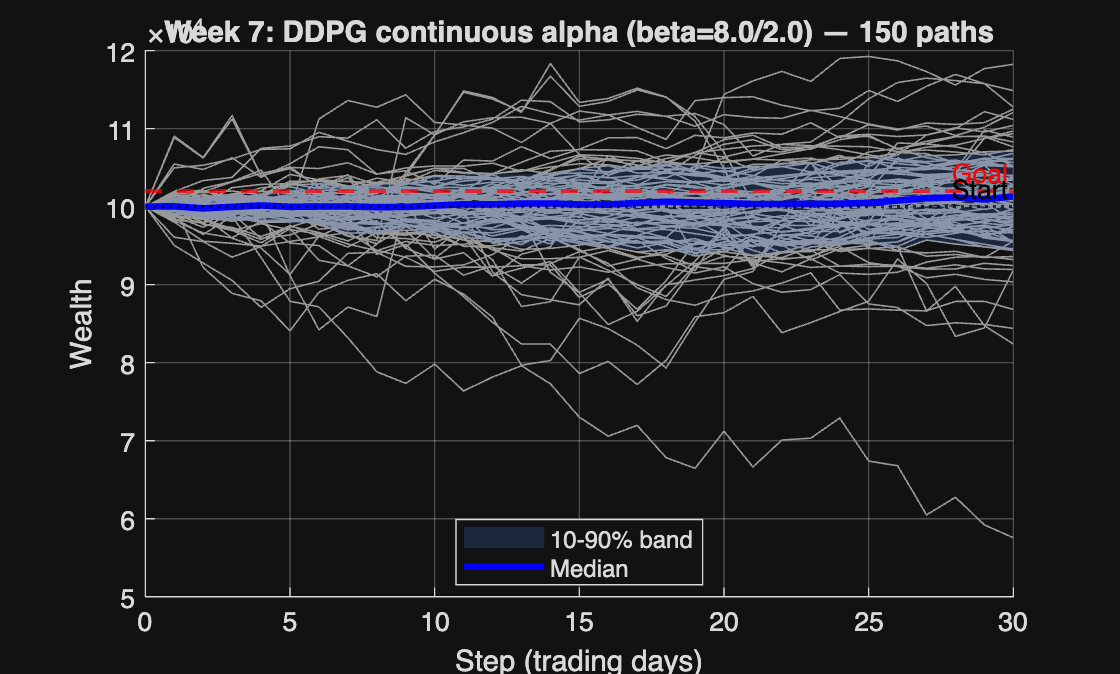

figure('Name','Hold-out wealth paths (Week 7 DDPG continuous action)');
hold on;

allPathsFlat = nan(nSeeds * numEvalEpisodes, horizonPeriods + 1);
rowCursor = 0;
for sIdx = 1:nSeeds
    paths = allWealthPathsBySeed{sIdx};
    for ep = 1:numel(paths)
        if ~isempty(paths{ep})
            rowCursor = rowCursor + 1;
            allPathsFlat(rowCursor, :) = paths{ep}';
        end
    end
end
allPathsFlat = allPathsFlat(1:rowCursor, :);

steps = 0:horizonPeriods;

for r = 1:size(allPathsFlat, 1)
    plot(steps, allPathsFlat(r, :), 'Color', [0.6 0.6 0.6 0.15], ...
        'LineWidth', 0.6, 'HandleVisibility', 'off');
end

p10 = prctile(allPathsFlat, 10, 1);
p90 = prctile(allPathsFlat, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');
plot(steps, median(allPathsFlat, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Week 7: DDPG continuous alpha (beta=%.1f/%.1f) — %d paths', ...
    BETA_HIGH, BETA_LOW, rowCursor));
legend('Location','best');
grid on;

## Local Functions

function w = alphaToWeights(alpha, W_frontier)
    % Map alpha in [0, 1] to a portfolio weight vector via linear
    % interpolation between adjacent efficient-frontier portfolios.
    %   alpha = 0   -> W_frontier(:, 1)         (most defensive)
    %   alpha = 1   -> W_frontier(:, end)       (most aggressive)
    %   alpha = 0.5 -> blend of middle two columns
    alpha = max(0, min(1, alpha));
    nCol  = size(W_frontier, 2);
    idxF  = 1 + alpha * (nCol - 1);
    iLo   = max(1, floor(idxF));
    iHi   = min(nCol, iLo + 1);
    frac  = idxF - iLo;
    w     = (1 - frac) * W_frontier(:, iLo) + frac * W_frontier(:, iHi);
end


function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;
end